# Analysing Data from the 125-Channel Child MEG System

Here we are analysing child data from the roving MMN task. We will be comparing the evoked response (or evoked fields) between trials with a deviant (unexpected) tone and the trial preceeding this, i.e. the pre-deviant (expected) tone. For more details on the paradigm, please see:

*Garrido, M. I., Friston, K. J., Kiebel, S. J., Stephan, K. E., Baldeweg, T., & Kilner, J. M. (2008). The functional anatomy of the MMN: a DCM study of the roving paradigm. Neuroimage, 42(2), 936-944.*

## Set-up Paths

Our first job will be to set up the paths to [MQ_MEG_Scripts](https://github.com/Macquarie-MEG-Research/MQ_MEG_Scripts) and [MEMES](https://github.com/Macquarie-MEG-Research/MEMES) and add these to MATLAB. Also please add the [Fieldtrip toolbox](http://www.fieldtriptoolbox.org/).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1. Set up paths
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Path to the raw data (make sure this ends with /)
data_path   = '/Volumes/Robert T5/2712/ReTHM/';

% Path to where the data should be saved (make sure this ends with /)
save_path   = '/Volumes/Robert T5/2712/processed/';

% Path to MQ_MEG_Scripts
% Download from https://github.com/Macquarie-MEG-Research/MQ_MEG_Scripts
path_to_MQ_MEG_Scripts = '/Users/rseymoue/Documents/GitHub/MQ_MEG_Scripts/';

% Path to MEMES
% Download from https://github.com/Macquarie-MEG-Research/MEMES
path_to_MEMES = '/Users/rseymoue/Documents/GitHub/MEMES/';

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. Add MQ_MEG_Scripts and MEMES to path
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

disp('Adding MQ_MEG_Scripts and MEMES to your MATLAB path');
warning(['Please note that MQ_MEG_Scripts and MEMES are designed for'...
    ' MATLAB 2016b or later and have been tested using Fieldtrip'...
    ' version 20181213']);
addpath(genpath(path_to_MQ_MEG_Scripts));
addpath(genpath(path_to_MEMES));

## Specify Subject ID

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3. Specifiy Subject ID
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subject = '2712';

## Specify Path to MEG Files

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4. Specify paths to confile, mrkfile, elpfile and hspfile
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

confile = [data_path '2712_SH_ME125_2017_10_04_B1_denoise_rethm.con'];

mrkfile = [data_path '2712_SH_ME125_2017_10_04_INI.mrk'];

elpfile = [data_path '2712_SH_ME125_2017_10_04.elp'];

hspfile = [data_path '2712_SH_ME125_2017_10_04.hsp'];

% Get the path to the saving directory
dir_name = save_path;
cd(dir_name);

## Check for Saturations

The 125-channel child system often picks up more low-frequency noise than the 160-channel adult system, which can result in "saturations" or periods of time in which the MEG channels flat-line. These time-periods should be identified and removed, or alternatively channels with a large amount of saturation should be ignored during data analysis. Saturation detection is done using the function `mq_detect_saturations`, and trial/channel removal using `mq_remove_sat `(not shown).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 5. Check for saturations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[sat] = mq_detect_saturations(dir_name,confile,0.01,'child','array');
save sat sat

## Downsample Headshape

For MEG-MRI Coregistration we need to downsample the headshape data using the new and improved `downsample_headshape_new` function.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 6. Downsample Headshape
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cfg                         = [];
cfg.facial_info             = 'yes';
cfg.remove_zlim             = 0;
cfg.downsample_facial_info  = 'yes';
headshape_downsampled = downsample_headshape_new(cfg,hspfile);

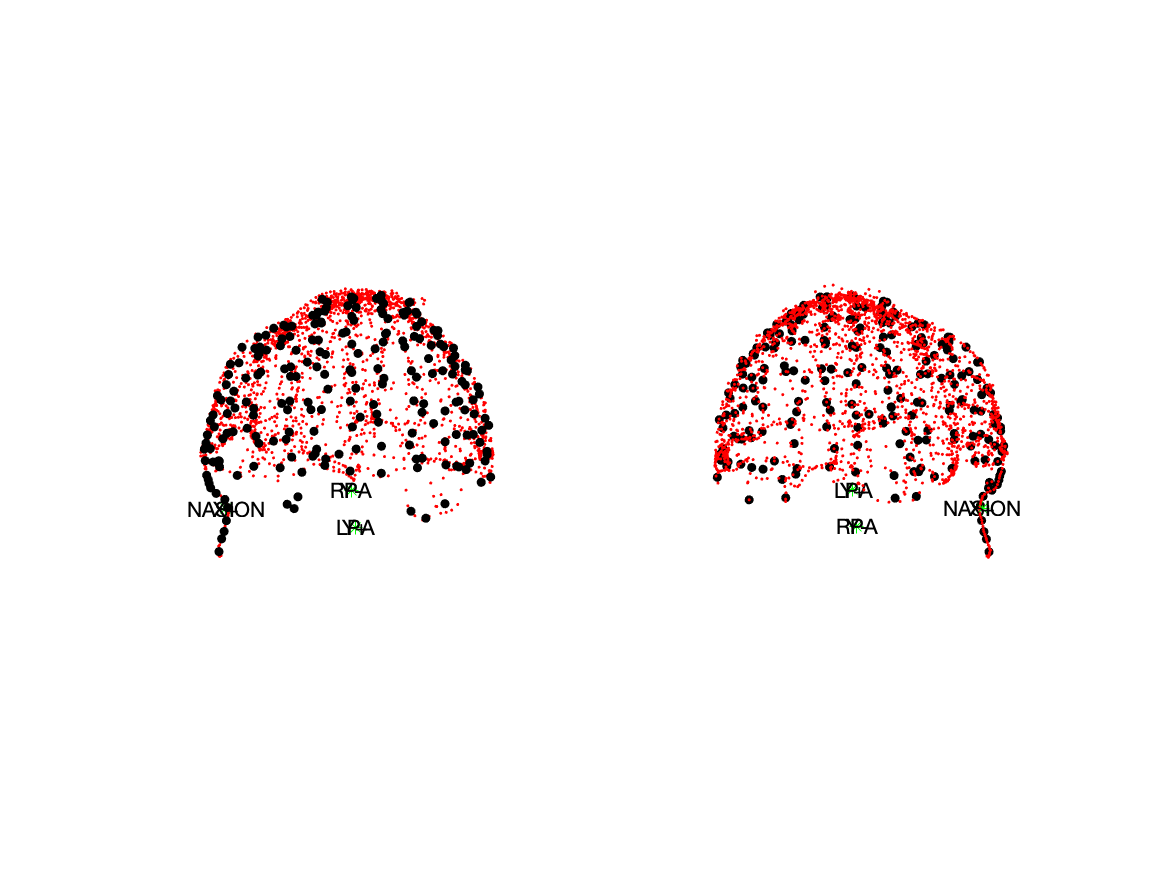

If your data has extensive facial information, please consider using the additional options to match with the MEMES database:

% cfg.facial_info_above_z           = remove points Xmm above the nasion 
%                                   on the z-axis (up-down)
% cfg.facial_info_below_z           = remove points Xmm below the nasion 
%                                   on the z-axis (up-down)
% cfg.facial_info_above_y           = remove points Xmm above the nasion 
%                                   on the y-axis (left-right) 
% cfg.facial_info_above_y           = remove points Xmm below the nasion 
%                                   on the y-axis (left-right) 
% cfg.facial_info_below_x           = remove points Xmm below the nasion 
%                                   on the x-axis (forwards-backwards)

## Realign Sensors

We can realign MEG sensors based on marker (head-position indicator) coils using `mq_realign_sens`.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 7. Realign Sensors
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[grad_trans] = mq_realign_sens(dir_name,elpfile,hspfile,...
    confile,mrkfile,'','rot3dfit');
print('grad_trans','-dpng','-r200');

## Read & Plot ReTHM (Head Tracking) Data

We have developed a function to read and plot the ReTHM data (continuous head tracking), held within the `.con` file: `get_reTHM_data`.

This helps the user estimate the amount of subject movement during the MEG recording and also whether there were any bad marker (head-position indicator) coils.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 8. Read & Plot ReTHM Data
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

bad_coil = '';
[head_movt, confound]  = get_reTHM_data(dir_name,confile,grad_trans,...
    hspfile,bad_coil,0.99)
save head_movt head_movt
save confound confound

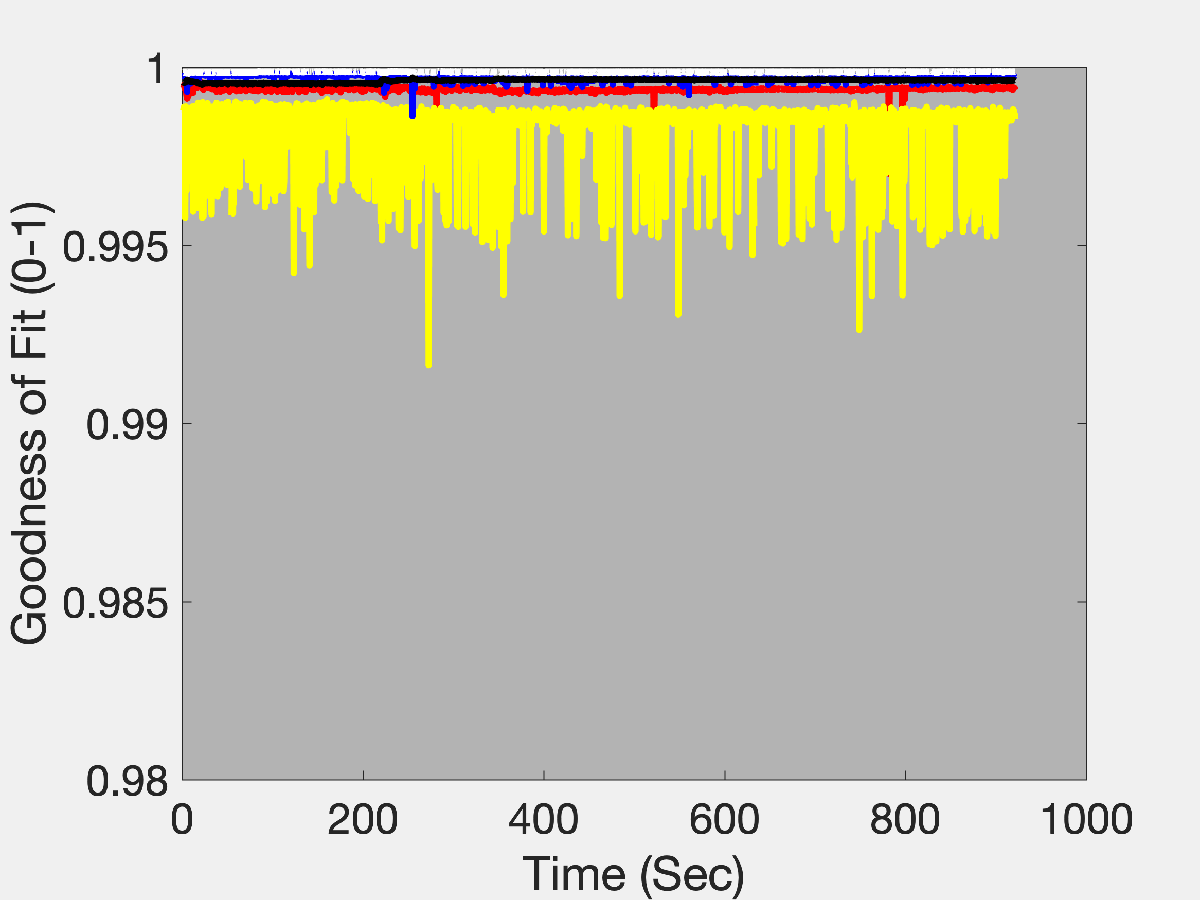

*The Goodness of Fit (GOF) is plotted. If this falls below a value of 0.99 (can be changed using the function) the tracking is considered poor and that particular measurement is ignored. Here the GOF is good for all coils.*

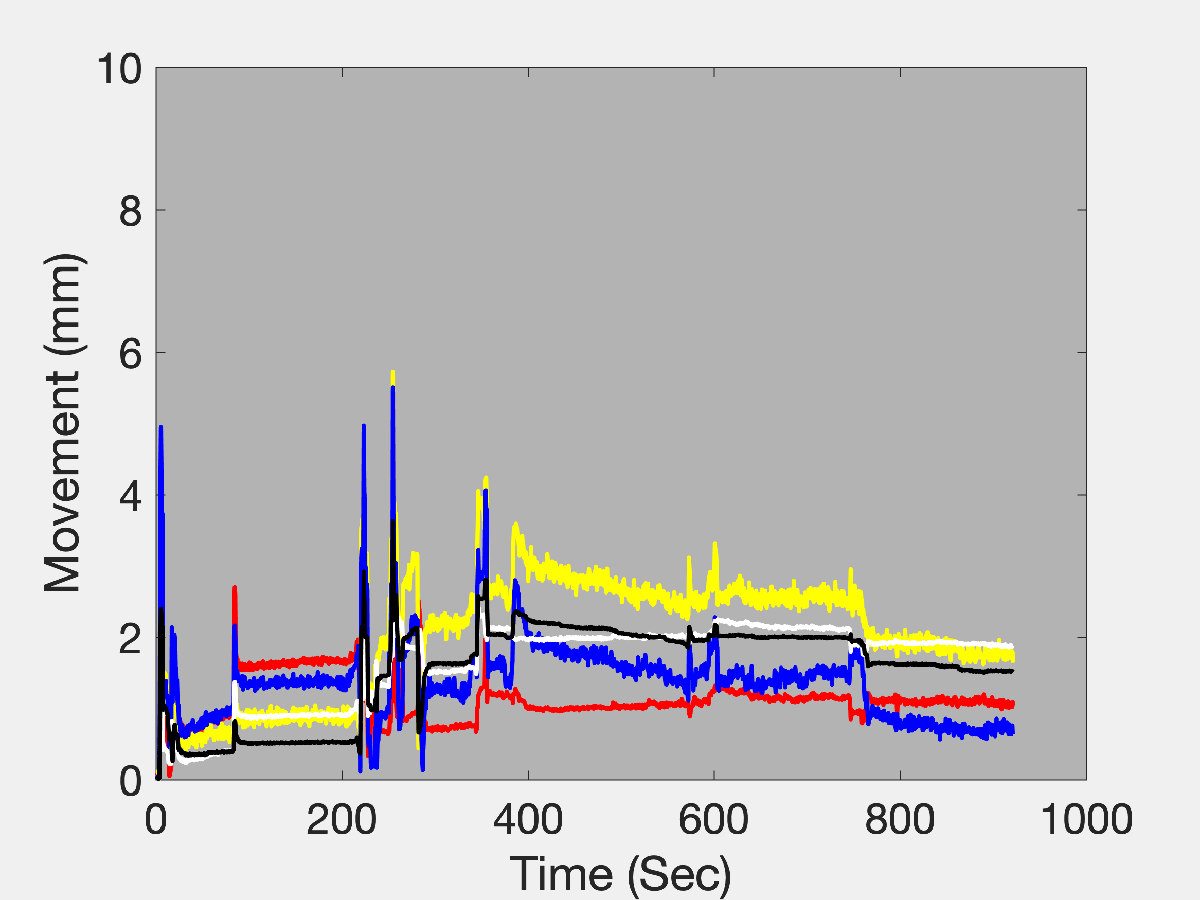

*Here we are plotting the movement of each coil over the length of the recording... in comparison with the FIRST measurement (at time = 0s).*

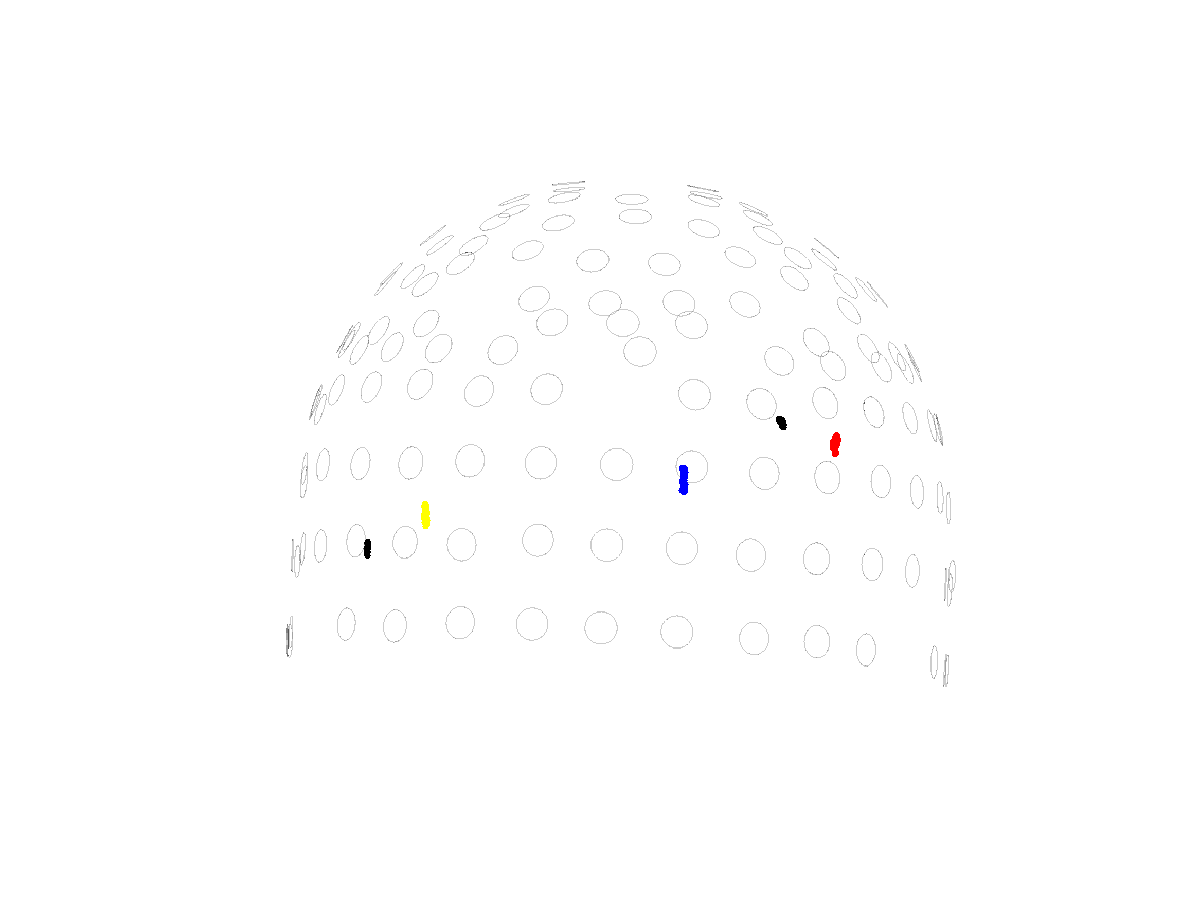

*Here we are plotting the location of the marker coils over the course of the recording. In this example, the subject has moved steadily lower in the MEG helmet.*

**NOTE: **If 1 or 2 coils have large % NaN values and/or low goofness of fit (under 0.99), condsider re-running the function with the argument: bad_coil = {'...'}. The function will then remove these bad coils. However you need at least 3 good coils for accurate head tracking.

**NOTE: **If you wish to perform head motion correction using your own custom approach (rather than MEG160), the translation and rotation values (compared with the first marker meaurement at time = 0s) are stored in the `confound` variable. In theory this can passed onto [`ft_regressconfound`](http://www.fieldtriptoolbox.org/reference/ft_regressconfound/).

## Preprocessing (1): Reading in Raw MEG Data

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 9. Read in raw MEG data & apply filters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% CD to correct directory
cd(dir_name);

% Epoch the whole dataset into one continous dataset and apply
% the appropriate filters
cfg                         = [];
cfg.headerfile              = confile;
cfg.datafile                = confile;
cfg.trialdef.triallength    = Inf;
cfg.trialdef.ntrials        = 1;
cfg                         = ft_definetrial(cfg)

cfg.continuous              = 'yes';
alldata                     = ft_preprocessing(cfg);

% Band-pass filter between 0.5-250Hz to help visualisation
cfg.continuous              = 'yes';
cfg.bpfilter                = 'yes';
cfg.bpfreq                  = [0.5 250];
alldata                     = ft_preprocessing(cfg);

% Deal with 50Hz line noise using a bandstop filter
cfg                         = [];
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [49.5 50.5];
alldata                     = ft_preprocessing(cfg,alldata);

% Deal with 100Hz line noise using a bandstop filter
cfg                         = [];
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [99.5 100.5];
alldata                     = ft_preprocessing(cfg,alldata);

% Create layout file for later and save
cfg                         = [];
cfg.grad                    = grad_trans;
lay                         = ft_prepare_layout(cfg, alldata);
save lay lay

% Cut out MEG channels
cfg                         = [];
cfg.channel                 = alldata.label(1:125);
alldata                     = ft_selectdata(cfg,alldata);


## Preprocessing (2): ICA

We run ICA on the continous data to remove obvious ocular and cardiac artefacts:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 10. Perform ICA on the continuous data & Remove ECG/EOG artefacts
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Downsample Data
alldata_orig    = alldata; %save the original CLEAN data for later use 
cfg             = []; 
cfg.resamplefs  = 150; %downsample frequency 
cfg.detrend     = 'no'; 
disp('Downsampling data');
alldata         = ft_resampledata(cfg, alldata);

% Run ICA
disp('About to run ICA using the Runica method')
cfg                 = [];
cfg.method          = 'fastica';
cfg.numcomponent    = 50;
cfg.feedback        = 'textbar';
comp                = ft_componentanalysis(cfg, alldata);

% Display Components - change layout as needed
cfg             = []; 
cfg.compscale   = 'local';
cfg.viewmode    = 'component'; 
cfg.layout      = lay;
cfg.position    = [1 1 800 700];
cfg.ylim        = [-1.149e-11 1.149e-11]
%cfg.ylim        = [ -2.8015e-11  5.7606e-11 ];
cfg.blocksize   = 5;
ft_databrowser(cfg, comp);

ft_hastoolbox('brewermap',1);
colormap123     = colormap(flipud(brewermap(64,'RdBu')));

% Decompose the original data as it was prior to downsampling 
disp('Decomposing the original data as it was prior to downsampling...');
cfg           = [];
cfg.unmixing  = comp.unmixing;
cfg.topolabel = comp.topolabel;
comp_orig     = ft_componentanalysis(cfg, alldata_orig);

%% The original data can now be reconstructed, excluding specified components
% This asks the user to specify the components to be removed
disp('Enter components in the form [1 2 3]')
comp2remove     = input('Which components would you like to remove?\n');
cfg             = [];
cfg.component   = [comp2remove]; %these are the components to be removed
data_clean      = ft_rejectcomponent(cfg, comp_orig,alldata_orig);

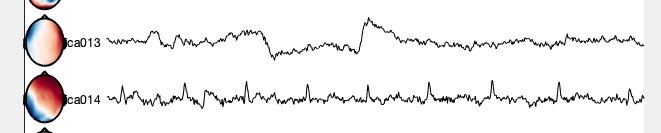

*Two very clear components with artefactual signal: ocular (13) and cardiac (14).*

## Preprocessing (3): Epoching

Here we use our custom trial function (`FindTriggers_AudioCh`) to correct triggers based on the audio channel. Deviant and pre-deviant trials are then selected.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 11. Epoch the data into trials
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cfg                         = [];
cfg.dataset                 = confile;
cfg.trialdef.prestim        = 0.1;         % pre-stimulus interval
cfg.trialdef.poststim       = 0.4;        % post-stimulus interval
cfg.trialdef.eventtype      = 'trigger';
cfg.trialdef.eventvalue     = [1 8];%Trigger numbers
cfg.Fs                      = 1000;
cfg.First_Channel           = 146; % First trigger channel
cfg.Last_Channel            = 158; % Last trigger channel
cfg.Audio_Channel           = 0;
cfg.fixed_offset            = 42; %defualt = []; 42ms for those without audio channel.
cfg.trialfun                = 'FindTriggers_AudioCh'; %
cfg                         = ft_definetrial(cfg);

data_epoched                = ft_redefinetrial(cfg,data_clean);
    
% Now we want to select deviant and predeviant trials of interest
% Get sequence of tones
event = data_epoched.cfg.event;

ggg = [];

for i = 1:length(event)
    ggg(i,1) = event(i).value;
end

% Find the deviant trials
deviant_trials = find(ggg == 1);

% Remove first trial
deviant_trials(1) = [];

% Now found deviant trials in which previous sequence length is greater
% than 3
fff = ggg(deviant_trials-1);
deviant_trials2 = deviant_trials(find(fff > 3));

% Get trial before (predeviant)
predeviant_trials = deviant_trials2-1;

fprintf('Found %d deviant trials\n', length(deviant_trials2));

fprintf('Found %d predeviant trials\n', length(predeviant_trials));

% Select data
cfg = [];
cfg.trials = deviant_trials2;
deviant = ft_selectdata(cfg,data_epoched);
cfg.trials = predeviant_trials;
predeviant = ft_selectdata(cfg,data_epoched);


## Preprocessing (4): Remove bad trials

A VERY important preprocessing step for child MEG data is to remove bad trials via visual inspection.

We also need to exclude two 'bad' channels during plotting: AG109 and AG052.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 12. Visually Inspect data for "bad" trials
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cfg                     = [];
cfg.channel             = {'MEG','-AG109','-AG052'};
cfg.colorgroups         = 'allblack';
cfg.viewmode            = 'vertical';
cfg.plotevents          = 'no'; 
cfg.preproc.hpfilter    = 'yes';
cfg.preproc.hpfreq      = 1;
title('Deviant');
ft_databrowser(cfg,deviant)
title('Pre-Deviant');
ft_databrowser(cfg,predeviant)

% Load the summary again so you can manually remove any bad trials
cfg                 = [];
cfg.method          = 'summary';
cfg.keepchannel     = 'yes';
deviant             = ft_rejectvisual(cfg, deviant);

cfg                 = [];
cfg.method          = 'summary';
cfg.keepchannel     = 'yes';
predeviant          = ft_rejectvisual(cfg, predeviant);

%% Plot the Clean Data
cfg = [];
cfg.channel             = {'MEG','-AG109','-AG052'};
cfg.colorgroups         = 'allblack';
cfg.viewmode            = 'vertical';
cfg.preproc.hpfilter    = 'yes';
cfg.preproc.hpfreq      = 1;
cfg.plotevents          = 'no'; 
ft_databrowser(cfg,deviant);
ft_databrowser(cfg,predeviant);

% Save to File
save deviant deviant
save predeviant predeviant

## Simple ERF Analysis

% Some very simple ERF analysis:
cfg                 = [];
cfg.layout          = lay;
cfg.linewidth       = 2;
figure; ft_multiplotER(cfg, ft_timelockanalysis([],deviant), ...
    ft_timelockanalysis([],predeviant));

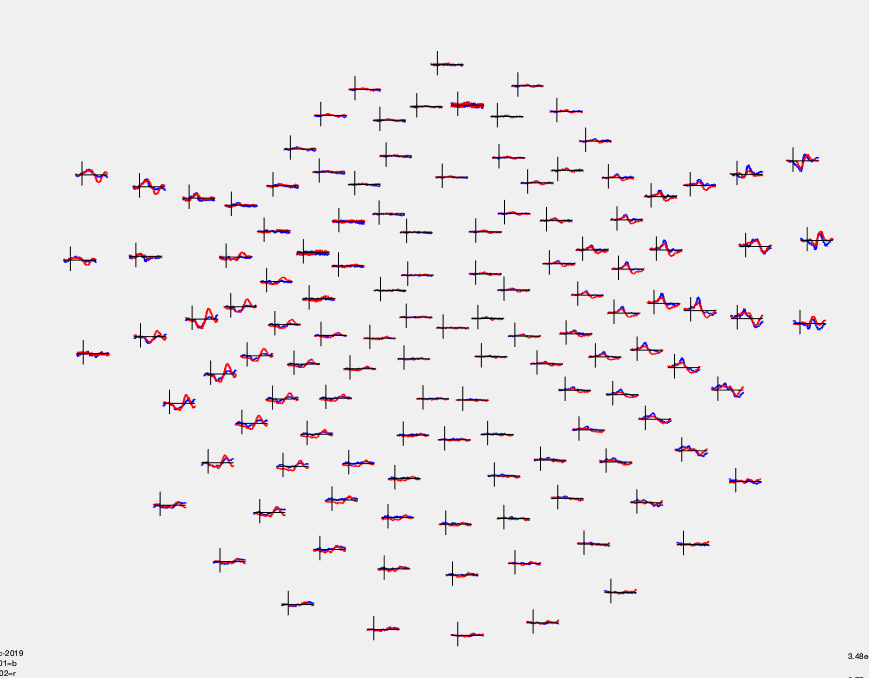

## MRI-MEG Coregistration with MEMES

Using the `child_MEMES` function, we match the headshape data against a library of age-appropriate template MRIs from the lab of Professor John E Richards. Please see [his site](https://jerlab.sc.edu/projects/neurodevelopmental-mri-database/) for more details and remember to include the approproate acknowledgments and citations.

If you use MEMES, we ask you to please cite:

*Robert Seymour. (2018, October 8). Macquarie-MEG-Research/MEMES: For Zenodo (Version v0.31). Zenodo. *[http://doi.org/10.5281/zenodo.1451031](http://doi.org/10.5281/zenodo.1451031)

**NOTE:** if your coreg looks bad, try adjusting the final argument which controls the weighting towards the facial points

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 13. Perform MRI-MEG Coreg with MEMES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Load grad_trans and headshape_downsampled
disp('Loading grad_trans and headshape_downsampled');

load('grad_trans');
load('headshape_downsampled');

% Define the path to MRI library

path_to_MRI_library = ['/Volumes/Robert T5/database_for_MEMES_child/'];

child_MEMES(dir_name,grad_trans,headshape_downsampled,...
    path_to_MRI_library,3);


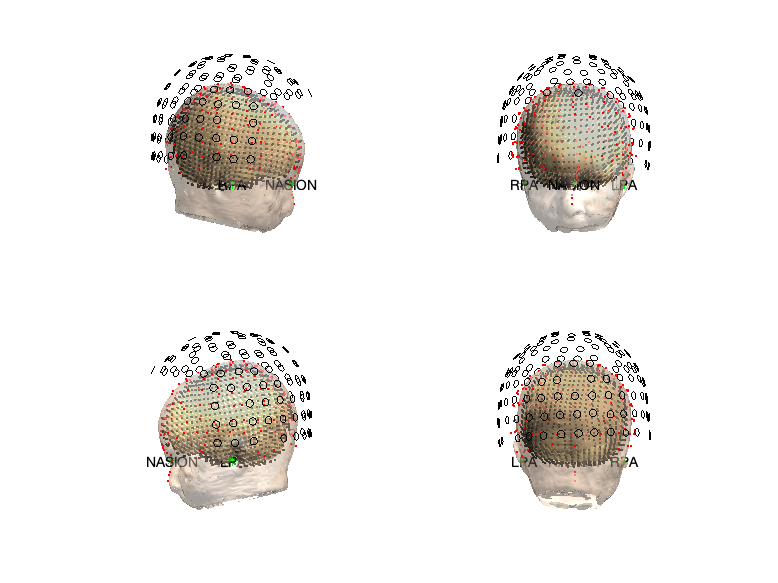

*Figure to show the alignment of the headmodel, sourcemodel, realigned MEG sensors and headshape.\*

## Source Analysis (1) - Auditory N1 Response

Using the output of MEMES, we can use an LCMV beamformer to localise the Auditory N1 Response at around 100ms

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 14. Source Localisation of Auditory N1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Load template sourcemodel (8mm)
load(['/Users/44737483/Documents/fieldtrip-20181213/template/'...
    'sourcemodel/standard_sourcemodel3d8mm.mat']);
template_grid = sourcemodel;
template_grid = ft_convert_units(template_grid,'mm');
clear sourcemodel;

%% Load sensor-level data data
load('deviant.mat');
load('predeviant.mat');

%% Load headmodel, sourcemodel and transformed MEG sensors
load('headmodel.mat');
load('sourcemodel3d.mat');
load('grad_trans.mat');

%% Remove bad channels
cfg         = [];
cfg.channel = {'MEG','-AG109','-AG052'};
deviant     = ft_selectdata(cfg,deviant);
predeviant  = ft_selectdata(cfg,predeviant);

%% Prepare leadfield
disp('Preparing Leadfield');
cfg             = [];
cfg.method      ='lcmv';
cfg.channel     = deviant.label;
cfg.grid        = sourcemodel3d;
cfg.headmodel   = headmodel;
cfg.grad        = grad_trans;
%cfg.reducerank      = 2; %(default = 3 for EEG, 2 for MEG)
cfg.normalize   = 'yes' ; %Normalise Leadfield: 'yes' for beamformer
lf = ft_prepare_leadfield(cfg);

% make a figure of the single shell headmodel, and grid positions
figure; hold on;
ft_plot_vol(headmodel,  'facecolor', 'cortex', 'edgecolor', 'none');
alpha 0.5; camlight;
ft_plot_mesh(lf.pos(lf.inside,:));
ft_plot_sens(grad_trans, 'style', 'r*'); view([0,0]);
print('lf_headmodel_sens','-dpng','-r100');

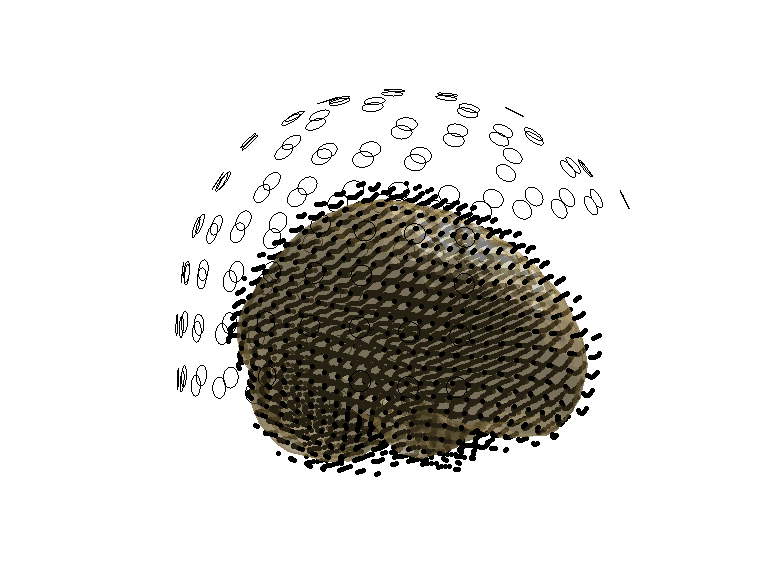

**NOTE:** Due to the "[centre of the head bias](http://www.fieldtriptoolbox.org/tutorial/beamformer/#exercise-3-center-of-head-bias)", here we use the Neural Activity Index (NAI), which is the power normalised with an estimate of the spatially inhomogeneous noise. Please note that this should ONLY be used to calculate the POWER. For dipole moments (i.e. for computing virtual electrodes) please comment out  `%cfg.lcmv.weightnorm    = 'nai'`.

**NOTE: **Here we use a common spatial filter computed across the time window (-0.1s to 0.4s). This ensures that any difference in power is not caused by different spatial filters.

%% Compute covariance
cfg                  = [];
cfg.covariance       = 'yes';
cfg.vartrllength     = 2;
cfg.covariancewindow = [-0.1 0.4];
avg_deviant          = ft_timelockanalysis(cfg,deviant);
avg_predeviant       = ft_timelockanalysis(cfg,predeviant);

%Make a dummy variable with covariance matrices averaged
avg_combined        = avg_deviant;
avg_combined.cov    = (avg_deviant.cov+avg_predeviant.cov)./2;

%% Source Analysis Proper (using LCMV)
cfg                    = [];
cfg.channel            = deviant.label;
cfg.grad               = grad_trans;
cfg.method             = 'lcmv';
cfg.grid               = lf;
cfg.headmodel          = headmodel;
cfg.lcmv.keepfilter    = 'yes';
cfg.lcmv.fixedori      = 'yes';
cfg.lcmv.projectnoise  = 'yes';
cfg.lcmv.weightnorm    = 'nai';
cfg.lcmv.lambda        = '5%';
sourceall              = ft_sourceanalysis(cfg, avg_combined);

save sourceall sourceall

% Now do source analysis for deviant and predeviant trials using the common
% filter
cfg.lcmv.filter        = sourceall.avg.filter;
source_deviant         = ft_sourceanalysis(cfg, avg_deviant);
source_predeviant      = ft_sourceanalysis(cfg, avg_predeviant);

% Replace .pos field with template_grid.pos
source_deviant.pos     = template_grid.pos;
source_predeviant.pos  = template_grid.pos;

% Remove cfg field to save memory
source_deviant         = rmfield(source_deviant,'cfg');
source_predeviant      = rmfield(source_predeviant,'cfg');

disp('Saving data');
save source_deviant source_deviant
save source_predeviant source_predeviant

Now we need to get the power from 0.1 to 0.15s post-stimulus onset, and compare this with an equivalen 0.05s baseline period:

%% Get N1 power
% Get time of interest
[deviant_N1_pre]        = get_source_pow(deviant,source_deviant,...
    [-0.1 -0.05]);
[deviant_N1_post]       = get_source_pow(deviant,source_deviant,...
    [0.1 0.15]);
[predeviant_N1_pre]     = get_source_pow(predeviant,source_predeviant,...
    [-0.1 -0.05]);
[predeviant_N1_post]    = get_source_pow(predeviant,source_predeviant,...
    [0.1 0.15]);

% Subtract post-pre
cfg = [];
cfg.parameter           = 'avg.pow';
cfg.operation           = 'subtract';
source_N1_deviant       = ft_math(cfg,deviant_N1_post,deviant_N1_pre);
source_N1_predeviant    = ft_math(cfg,predeviant_N1_post,predeviant_N1_pre);

% 2D Plot
cfg                     = [];
cfg.funparameter        = 'pow';
ft_sourceplot(cfg,source_N1_deviant);
title('DEVIANT N1');
ft_sourceplot(cfg,source_N1_predeviant);
title('PREDEVIANT N1');

% Display Max MNI Coordinate
[MNI_coord_of_max]      = find_max_MNI(source_N1_deviant,...
    template_grid,'yes');

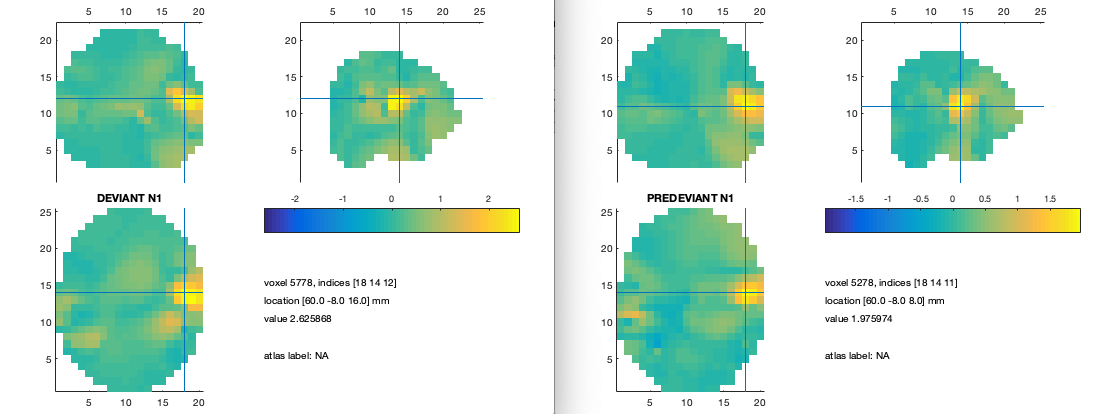

We can next interpolate the data onto the SPM T1 Template Brain

%% Interpolate
mri         = ft_read_mri(['/Users/44737483/Documents/fieldtrip-20181213/'...
    'template/anatomy/single_subj_T1.nii']);

% Interpolate onto SPM brain
cfg                         = [];
cfg.voxelcoord              = 'no';
cfg.parameter               = 'pow';
cfg.interpmethod            = 'nearest';
source_N1_predeviant_interp    = ft_sourceinterpolate(cfg, ...
    source_N1_predeviant, mri);

%% Plot
cfg                 = [];
cfg.funparameter    = 'pow';
cfg.zlim            = 'maxabs';
ft_sourceplot(cfg,source_N1_predeviant_interp);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
saveas(gcf,'sourceN1.png');

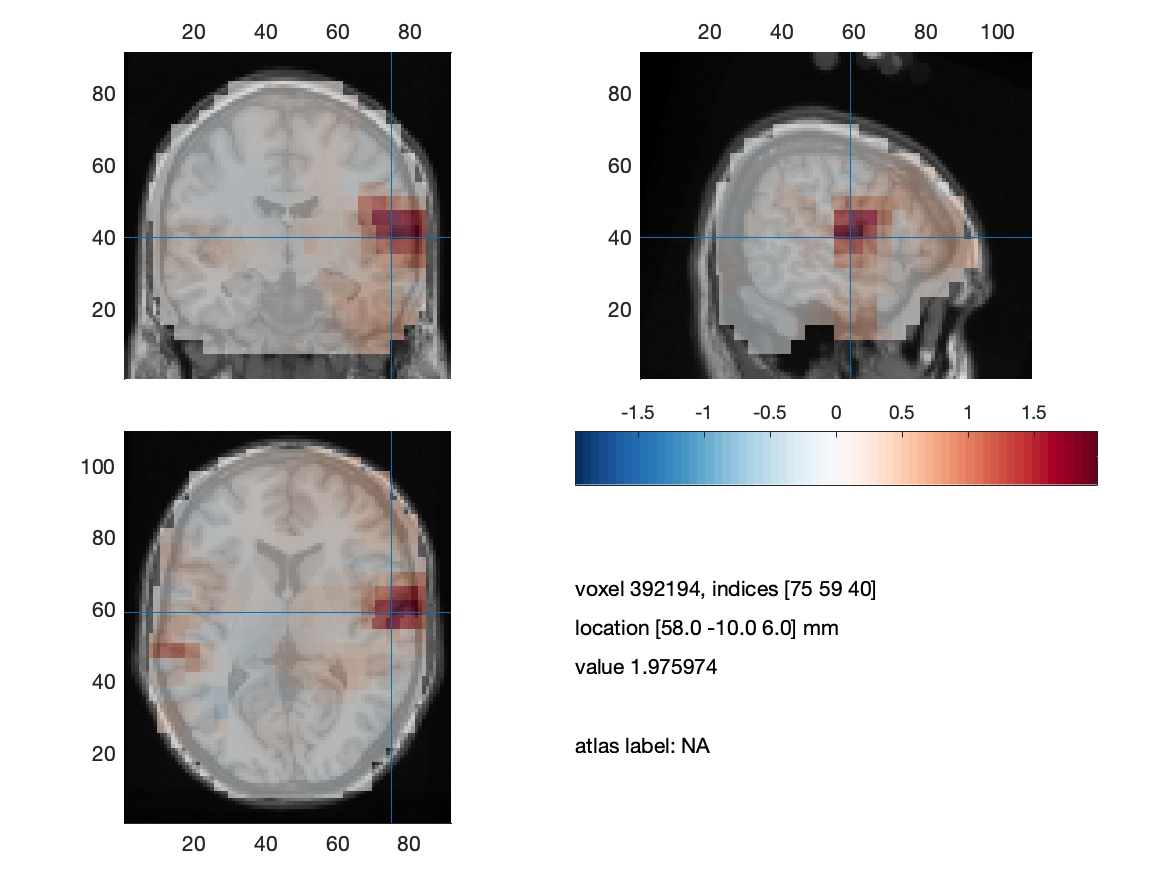

## Source Analysis (2) - Auditory Mismatch Field Response

From the sensor-level data for this subject, we noticed there was a large difference in the evoked responses from around 0.1 to 0.13s post-stimulus onset, between the deviant and predeviant trials. Using the following code, we can localise the source of this "mismatch field" response (i.e. the difference between deviant and pre-deviant trials):

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 15. Source Localisation of Auditory MMF
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Get MMF power
% Get time of interest
[deviant_MMF]           = get_source_pow(deviant,source_deviant,...
    [0.105933 0.133583]);
[predeviant_MMF]        = get_source_pow(predeviant,source_predeviant,...
    [0.105933 0.133583]);

% Subtract deviant power from predeviant power
cfg = [];
cfg.parameter           = 'avg.pow';
cfg.operation           = 'subtract';
source_MMF              = ft_math(cfg,deviant_MMF,predeviant_MMF);

% Plot in 2D
cfg                 = [];
cfg.funparameter    = 'pow';
ft_sourceplot(cfg,source_MMF);
title('DEVIANT - PREDEVIANT');

% Display Max MNI Coordinate
[MNI_coord_of_max] = find_max_MNI(source_MMF,template_grid,'yes');

%% Interpolate onto SPM brain
cfg                         = [];
cfg.voxelcoord              = 'no';
cfg.parameter               = 'pow';
cfg.interpmethod            = 'nearest';
source_MMF_interp           = ft_sourceinterpolate(cfg,source_MMF, mri);

%% Plot in 2D
cfg                 = [];
cfg.funparameter    = 'pow';
cfg.zlim            = 'maxabs';
ft_sourceplot(cfg,source_MMF_interp);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
title('DEVIANT - PREDEVIANT');
saveas(gcf,'sourceMMF.png');